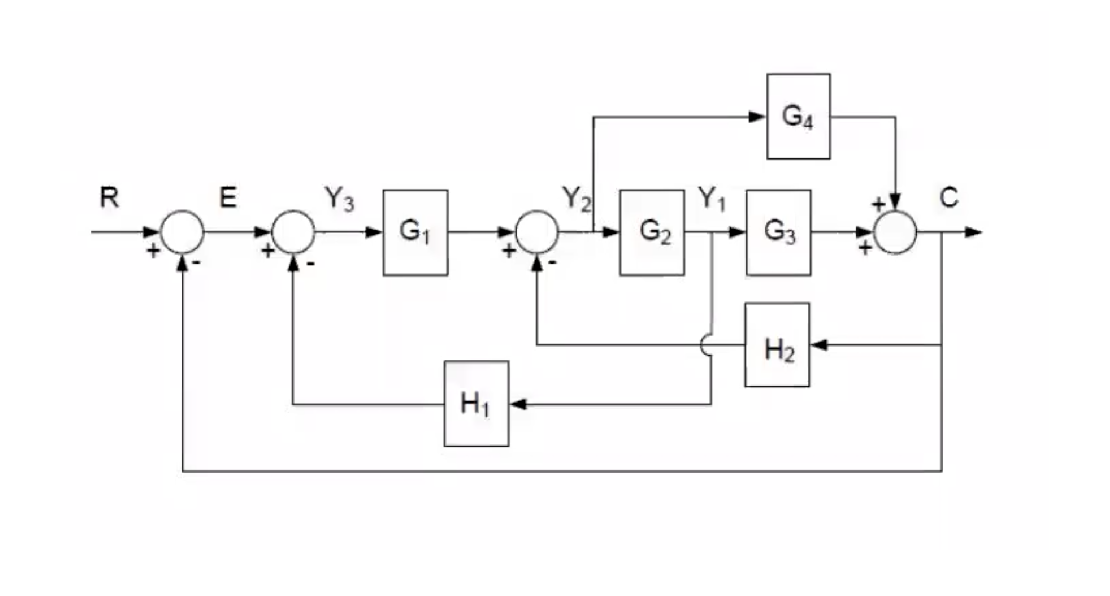

imshow(imread("HW1/Example.png"))


syms C R E Y_1 Y_2 Y_3 G_1 G_2 G_3 G_4 H_1 H_2

% basic equations
eqn1 = C == G_4*Y_2 + G_3*Y_1

$$eqn1 = C=G_{3}\,Y_{1}+G_{4}\,Y_{2}$$

eqn2 = Y_1 == G_2*Y_2

$$eqn2 = Y_{1}=G_{2}\,Y_{2}$$

eqn3 = Y_2 == G_1*Y_3 - C*H_2

$$eqn3 = Y_{2}=G_{1}\,Y_{3}-C\,H_{2}$$

eqn4 = Y_3 == E - Y_1*H_1

$$eqn4 = Y_{3}=\text{E}-H_{1}\,Y_{1}$$

eqn5 = E == R - C

$$eqn5 = \text{E}=R-C$$


%substitutions
Es = rhs (eqn5)

$$Es = R-C$$

Y_3s = solve (subs (eqn4, E, Es), Y_3)

$$Y\_3s = R-C-H_{1}\,Y_{1}$$

Y_2s = solve(subs(eqn3, Y_3,Y_3s), Y_2)

$$Y\_2s = -C\,H_{2}-G_{1}\,\left(C-R+H_{1}\,Y_{1}\right)$$

Y_1s = solve (subs(eqn2, Y_2,Y_2s), Y_1)

$$Y\_1s = -\frac{G_{2}\,\left(C\,H_{2}+G_{1}\,\left(C-R\right)\right)}{G_{1}\,G_{2}\,H_{1}+1}$$

Cs_int = subs (eqn1, [Y_1,Y_2], [Y_1s,Y_2s])

$$Cs\_int = C=-G_{4}\,\left(C\,H_{2}+G_{1}\,\left(C-R+H_{1}\,Y_{1}\right)\right)-\frac{G_{2}\,G_{3}\,\left(C\,H_{2}+G_{1}\,\left(C-R\right)\right)}{G_{1}\,G_{2}\,H_{1}+1}$$

Cs = C == solve (subs (Cs_int, Y_1, Y_1s),C)

$$Cs = C=\frac{G_{1}\,G_{4}\,\left(R-\frac{G_{1}\,G_{2}\,H_{1}\,R}{G_{1}\,G_{2}\,H_{1}+1}\right)+\frac{G_{1}\,G_{2}\,G_{3}\,R}{G_{1}\,G_{2}\,H_{1}+1}}{G_{4}\,\left(H_{2}-G_{1}\,\left(\frac{G_{2}\,H_{1}\,\left(G_{1}+H_{2}\right)}{G_{1}\,G_{2}\,H_{1}+1}-1\right)\right)+\frac{G_{2}\,G_{3}\,\left(G_{1}+H_{2}\right)}{G_{1}\,G_{2}\,H_{1}+1}+1}$$

Css = C == collect (simplify(rhs(Cs)) ,R)

$$Css = C=\frac{G_{1}\,\left(G_{4}+G_{2}\,G_{3}\right)}{G_{1}\,G_{4}+G_{4}\,H_{2}+G_{1}\,G_{2}\,G_{3}+G_{1}\,G_{2}\,H_{1}+G_{2}\,G_{3}\,H_{2}+1}\,R$$

TF = C/R == rhs(Css)/R

$$TF = \frac{C}{R}=\frac{G_{1}\,\left(G_{4}+G_{2}\,G_{3}\right)}{G_{1}\,G_{4}+G_{4}\,H_{2}+G_{1}\,G_{2}\,G_{3}+G_{1}\,G_{2}\,H_{1}+G_{2}\,G_{3}\,H_{2}+1}$$


% alternative method, solve all equations simultaneously
eqns = [eqn1, eqn2, eqn3, eqn4, eqn5]

$$eqns = \left(\begin{array}{ccccc} C=G_{3}\,Y_{1}+G_{4}\,Y_{2} & Y_{1}=G_{2}\,Y_{2} & Y_{2}=G_{1}\,Y_{3}-C\,H_{2} & Y_{3}=\text{E}-H_{1}\,Y_{1} & \text{E}=R-C \end{array}\right)$$

S=solve (eqns, [C,Y_1,Y_2,Y_3, E])

S = struct with fields:
      C: (G_1*G_4*R + G_1*G_2*G_3*R)/(G_1*G_4 + G_4*H_2 + G_1*G_2*G_3 + G_1*G_2*H_1 + G_2*G_3*H_2 + 1)
    Y_1: (G_1*G_2*R)/(G_1*G_4 + G_4*H_2 + G_1*G_2*G_3 + G_1*G_2*H_1 + G_2*G_3*H_2 + 1)
    Y_2: (G_1*R)/(G_1*G_4 + G_4*H_2 + G_1*G_2*G_3 + G_1*G_2*H_1 + G_2*G_3*H_2 + 1)
    Y_3: (R*(G_4*H_2 + G_2*G_3*H_2 + 1))/(G_1*G_4 + G_4*H_2 + G_1*G_2*G_3 + G_1*G_2*H_1 + G_2*G_3*H_2 + 1)
      E: (R*(G_4*H_2 + G_1*G_2*H_1 + G_2*G_3*H_2 + 1))/(G_1*G_4 + G_4*H_2 + G_1*G_2*G_3 + G_1*G_2*H_1 + G_2*G_3*H_2 + 1)


EQ1 = C == collect(S.C,R)

$$EQ1 = C=\frac{G_{1}\,G_{4}+G_{1}\,G_{2}\,G_{3}}{G_{1}\,G_{4}+G_{4}\,H_{2}+G_{1}\,G_{2}\,G_{3}+G_{1}\,G_{2}\,H_{1}+G_{2}\,G_{3}\,H_{2}+1}\,R$$

EQ2 = C/R == rhs (EQ1/R)

$$EQ2 = \frac{C}{R}=\frac{G_{1}\,G_{4}+G_{1}\,G_{2}\,G_{3}}{G_{1}\,G_{4}+G_{4}\,H_{2}+G_{1}\,G_{2}\,G_{3}+G_{1}\,G_{2}\,H_{1}+G_{2}\,G_{3}\,H_{2}+1}$$